# Identify Parachutes

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

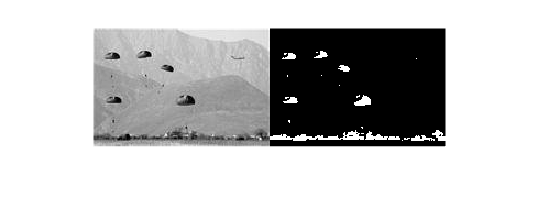

parachutes = imread("./images/parachutesGS.jpg");
paraBW = parachutes < 90;
imshowpair(parachutes, paraBW, "montage")

## Task 1

You can create a neighborhood, or *structuring element*, using the `strel` function by specifying a shape and size.

`SE` `=` `strel``(``"disk"``,``r``)``;`

There are many different shapes you can choose. For a disk, you need to specify the radius.

SE = strel("disk", 7)

SE = strel is a disk shaped structuring element with properties:

      Neighborhood: [13×13 logical]
    Dimensionality: 2


## Task 2

A closing operation emphasizes bright spots. In a binary image, that means foreground is emphasized. It can be used to fill out indentations in a segmentation.

`BW2` `=` `imclose``(``BW``,``SE``)``;`

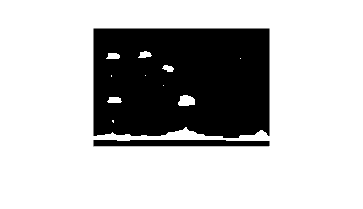

paraBW = imclose(paraBW, SE);
imshow(paraBW)

## Task 3

The bright sides of the parachutes are more filled out in the segmentation, but there is still a bit of noise where the boxes are hanging and from the airplane. 

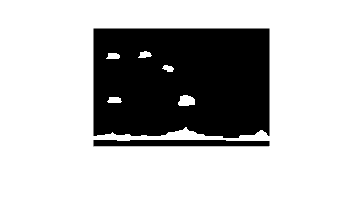

paraBW = bwareaopen(paraBW, 20);
imshow(paraBW)

## Task 4

The land at the bottom touches the border. You can remove foreground touching the border with `imclearborder`.

`BW2` `=` `imclearborder``(``BW``)``;`

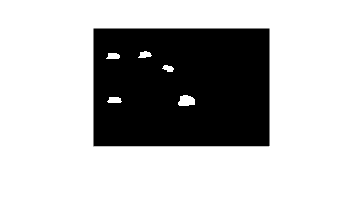

paraBW = imclearborder(paraBW);
imshow(paraBW)